close all; clear; clc;syms s

# EJERCICIO 6

### Función de transferencia del controlador PID

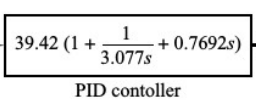

kp    = 39.42;
kir   = 1/3.077;
kdr   = 0.7692;
numC = [kdr*kp kp kir*kp];
denC = [0 1 0];
Gc   = tf(numC, denC)

Gc =
 
  30.32 s^2 + 39.42 s + 12.81
  ---------------------------
               s
 
Continuous-time transfer function.



aux1  = poly2sym(numC, s);
aux2  = poly2sym(denC, s);
Gc_sym = (aux1/aux2)

$$Gc\_sym = \frac{\frac{8534845963223679\,s^{2}}{281474976710656}+\frac{1971\,s}{50}+\frac{39420}{3077}}{s}$$

### Función de transferencia de la planta

numP = 1;
denP = conv([1 0], conv([1 1], [1 5]));
Gp   = tf(numP, denP)

Gp =
 
          1
  -----------------
  s^3 + 6 s^2 + 5 s
 
Continuous-time transfer function.



aux1  = poly2sym(numP, s);
aux2  = poly2sym(denP, s);
Gp_sym = (aux1/aux2)

$$Gp\_sym = \frac{1}{s^{3}+6\,s^{2}+5\,s}$$

### **Sistema con controlador PID**

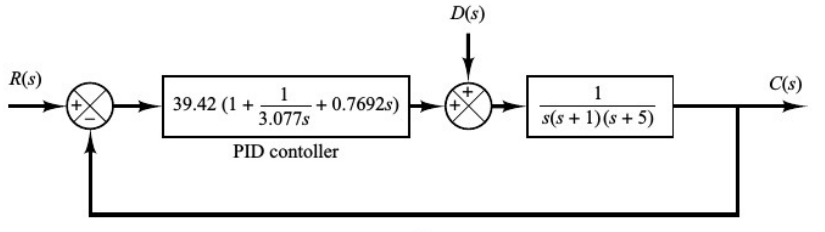

### Función de transferencia a LC respecto de la referencia

GPID = (Gp*Gc)/(1 + Gp*Gc)

GPID =
 
         30.32 s^6 + 221.4 s^5 + 400.9 s^4 + 274 s^3 + 64.06 s^2
  ----------------------------------------------------------------------
  s^8 + 12 s^7 + 76.32 s^6 + 281.4 s^5 + 425.9 s^4 + 274 s^3 + 64.06 s^2
 
Continuous-time transfer function.



GPID_sym = collect((Gp_sym*Gc_sym)/(1 + Gp_sym*Gc_sym))

$$GPID\_sym = \frac{656543025720981507075\,s^{2}+853540075040277528576\,s+277393589548351488000}{21652462583467212800\,s^{4}+129914775500803276800\,s^{3}+764805338638317571075\,s^{2}+853540075040277528576\,s+277393589548351488000}$$

[aux1, aux2] = numden(GPID_sym);
aux1         = double(sym2poly(aux1));
aux2         = double(sym2poly(aux2));
GPID_sym     = tf(aux1, aux2)

GPID_sym =
 
                 6.565e20 s^2 + 8.535e20 s + 2.774e20
  ------------------------------------------------------------------
  2.165e19 s^4 + 1.299e20 s^3 + 7.648e20 s^2 + 8.535e20 s + 2.774e20
 
Continuous-time transfer function.



### Función de transferencia a LC respecto de la perturbación

GPIDd = Gp/(1 + Gp*Gc)

GPIDd =
 
                          s^4 + 6 s^3 + 5 s^2
  --------------------------------------------------------------------
  s^7 + 12 s^6 + 76.32 s^5 + 281.4 s^4 + 425.9 s^3 + 274 s^2 + 64.06 s
 
Continuous-time transfer function.



### Sistema con controlador I-PD

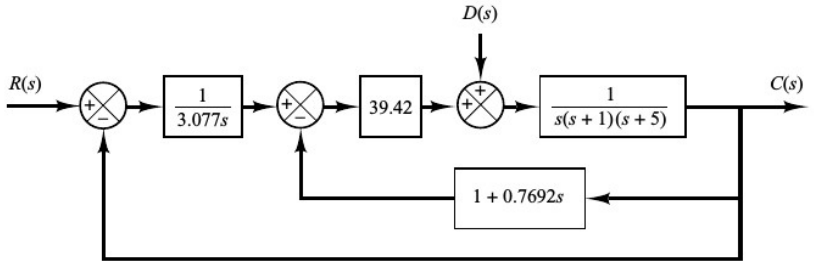

### Función de transferencia del bloque PD

GPD = tf([kdr 1], 1)              % Función de transferencia del bloque PD

GPD =
 
  0.7692 s + 1
 
Continuous-time transfer function.



### Función de transferencia del lazo interno PD

GPDLC = kp*Gp/(1 + kp*Gp*GPD)     % Función de transferencia a LC del lazo interno PD

GPDLC =
 
               39.42 s^3 + 236.5 s^2 + 197.1 s
  ----------------------------------------------------------
  s^6 + 12 s^5 + 76.32 s^4 + 281.4 s^3 + 413.1 s^2 + 197.1 s
 
Continuous-time transfer function.



### Función de transferencia del bloque I

GI = tf(kir, [1 0])

GI =
 
  0.325
  -----
    s
 
Continuous-time transfer function.



### Función de transferencia con controlador I-PD respecto a la referencia

GI_PD   = GI*GPDLC/(1 + GI*GPDLC) % Función de transferencia completa a LC respecto a la referencia

GI_PD =
 
                                                                                                                      
           12.81 s^10 + 230.6 s^9 + 1964 s^8 + 1.024e04 s^7 + 3.181e04 s^6 + 5.23e04 s^5 + 4.161e04 s^4 + 1.263e04 s^3
                                                                                                                      
  ------------------------------------------------------------------------------------------------------------------------------
                                                                                                                                
  s^14 + 24 s^13 + 296.6 s^12 + 2394 s^11 + 1.342e04 s^10 + 5.349e04 s^9 + 1.489e05 s^8 + 2.728e05 s^7 + 3.134e05 s^6           
                                                                                                                                
                                                                                    + 2.152e05 s^5 + 8.046e04 s^4 + 1

### Función de transferencia con controlador I-PD respecto a la perturbación

Es la misma función de transferencia que respecto del controlador PID común. Se obtiene esta función de transferencia analizando el diagrama de bloques. Queda en el lazo de retorno la función de transferencia del controlador PID cuando se hace nula la refrencia, y en el lazo directo queda la función de transferencia de la planta.

GI_PDd  = Gp/(1 + Gc*Gp); 

## Comparación de las respuestas

#### Respuesta con controlador PID respecto a la referencia

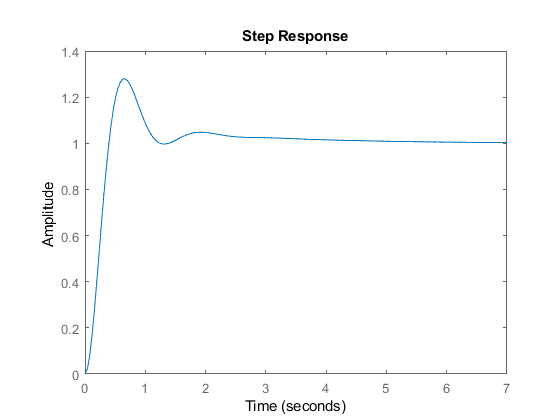

step(GPID)

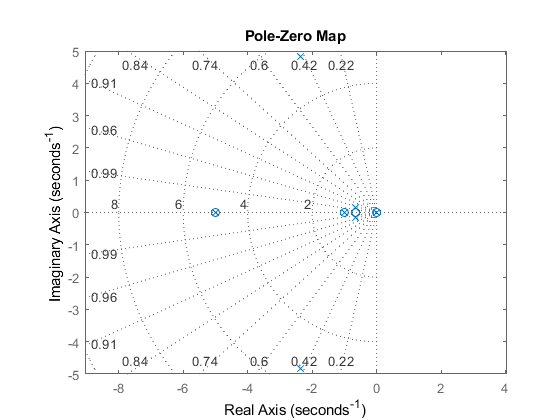

pzmap(GPID); grid on; axis('equal');

[P, Z] = pzmap(GPID)

P =    0.0000 + 0.0000i
   0.0000 + 0.0000i
  -2.3514 + 4.8215i
  -2.3514 - 4.8215i
  -5.0000 + 0.0000i
  -1.0000 + 0.0000i
  -0.6486 + 0.1568i
  -0.6486 - 0.1568i


Z =          0
         0
   -5.0000
   -1.0000
   -0.6553
   -0.6448


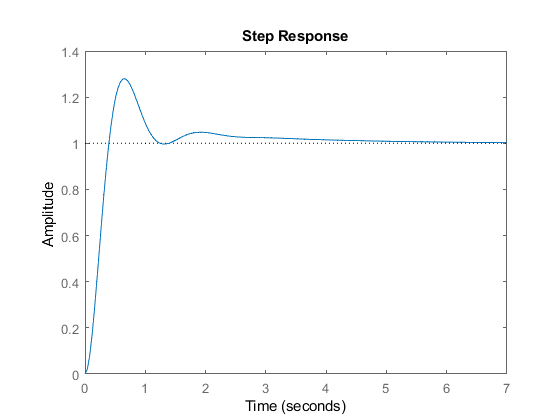

step(GPID_sym)

aux1 = numC

aux1 =    30.3219   39.4200   12.8112


aux2 = [denP 0] + [0 0 kdr*kp kp kir*kp]

aux2 =     1.0000    6.0000   35.3219   39.4200   12.8112


G_aux = tf(aux1, aux2)

G_aux =
 
         30.32 s^2 + 39.42 s + 12.81
  -----------------------------------------
  s^4 + 6 s^3 + 35.32 s^2 + 39.42 s + 12.81
 
Continuous-time transfer function.



t = 0:0.000001:10

t =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


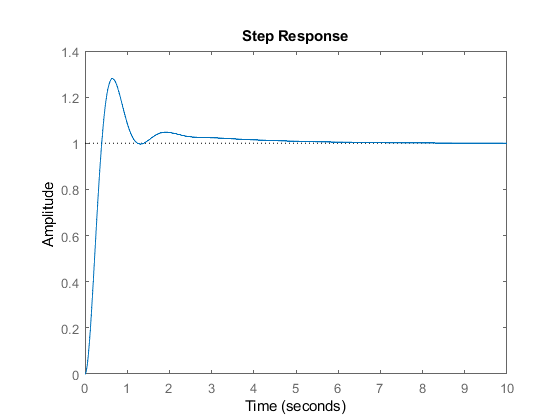

step(G_aux, t)

aux1 = conv(numC, [denP 0])

aux1 =    30.3219  221.3512  400.9405  273.9671   64.0559         0         0


aux2 = conv([denP 0], [denP 0])

aux2 =      1    12    46    60    25     0     0     0     0


aux2 = aux2 + [0 0 conv(numC, [denP 0])]

aux2 =     1.0000   12.0000   76.3219  281.3512  425.9405  273.9671   64.0559         0         0


G_aux = tf(aux1, aux2)

G_aux =
 
         30.32 s^6 + 221.4 s^5 + 400.9 s^4 + 274 s^3 + 64.06 s^2
  ----------------------------------------------------------------------
  s^8 + 12 s^7 + 76.32 s^6 + 281.4 s^5 + 425.9 s^4 + 274 s^3 + 64.06 s^2
 
Continuous-time transfer function.



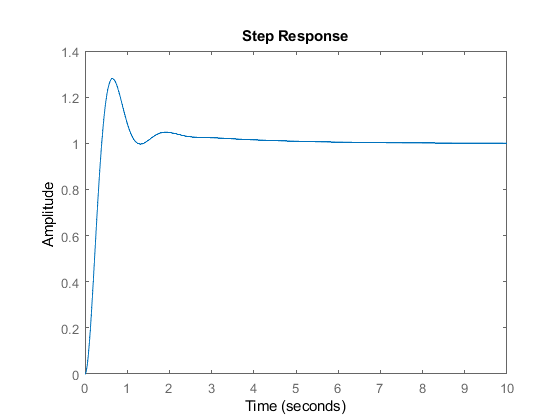

step(G_aux, t)

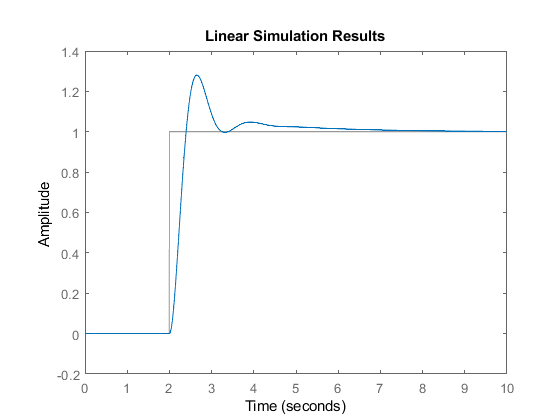

R = zeros(size(t));           % Inicializar R con ceros

% Tramo creciente lineal entre t = 1 y t = 2
R(t >= 1 & t < 1.0001) = t(t >= 1 & t < 1.0001) - 1;

% Tramo constante R = 1 desde t >= 2
R(t >= 2) = 1;
lsim(G_aux, R, t)

Entonces hay que notar que hay cancelación polo/zero de dos polos reales en -1 y -5.

#### Respuesta con controlador I-PD

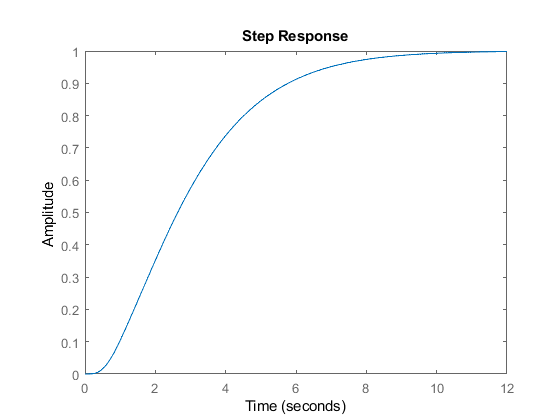

step(GI_PD)

# EJERCICIO 7

### Respuesta con controlador PID a la perturbación

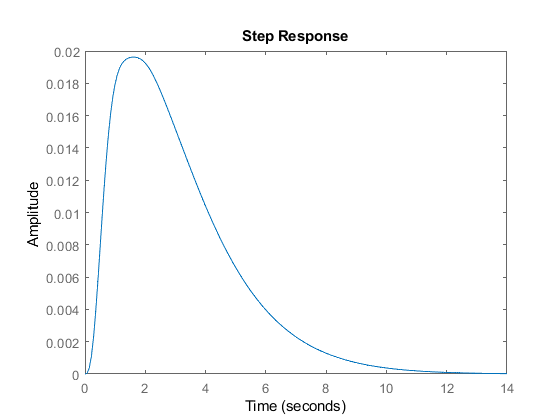

step(GPIDd)

### Respuesta con controlador I-PD a la perturbación

step(GI_PDd)